# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

姓名：    王晨晖       学号：   24307163       专业：   电子信息工程    

## 实验二 卷积与系统频域分析

## 一、实验目的

- 通过实验进一步了解卷积定理，了解卷积的过程

- 加深对离散系统变换域分析——z变换的理解

- 掌握进行z变换和z反变换的基本方法，了解部分分式法在z反变换中的应用

- 掌握利用Matlab进行离散系统零极点分析方法

- 掌握利用Matlab分析离散系统幅频响应和相频响应的方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

卷积：两信号之间的滑动匹配并累加，翻转平移，卷积后的信号长度会为两者的叠加。在LTI系统中，时域上，输入信号与系统函数的卷积即为输出信号。

系统的因果性：系统的输出信号仅依赖于当前和过去的输入，而与未来输入无关，表现为h(n)<0,n<0。在Z变换域中表现为收敛域包含无穷远点。

系统的稳定性：系统任意的有界输入都会产生有界输出。在Z变换域中表现为收敛域包含单位圆。

低通滤波器：仅允许低频（低于截止频率）的信号通过

高通滤波器：仅允许高频的信号通过

带通滤波器：只允许某一频带范围通过，低于或高于该频段的信号将被抑制

带阻滤波器：抑制某一频带范围，允许该频带范围之外的信号通过

群延时：信号包络（或窄带调制信号）在系统中各频率分量被“延迟”了多少。

## 四、实验所用MATLAB函数

conv:进行两个序列间的卷积运算 conv(xn,hn)

dlsim(b,a,x):求输入信号为x时系统的响应

ztrans: 返回无限长序列函数x(n)的z变换 ztrans(xn,n,z)

iztrans: 求函数X(z)的z反变换x(n)  iztrans(f)

residuez: 有理多项式的部分分式展开 residuez(b,a)

freqz: 求离散系统频响特性的函数 freqz(a,b,n)

## 五、实验内容、方法、代码与结果

### **题目1**：已知${\mathbf{x}}_1 \left(\mathbf{n}\right)=R_{10} \left(n\right)\textrm{，0}\le n\le 9$，${\mathbf{x}}_2 \left(\mathbf{n}\right)=R_{15} \left(n\right)\textrm{，0}\le n\le 14$，求两个信号的卷积${\mathit{\mathbf{x}}\left(n\right)=\mathit{\mathbf{x}}}_1 \left(\mathbf{n}\right)$*${\mathbf{x}}_2 \left(\mathbf{n}\right)$，注意n的非零取值范围应为0~23。

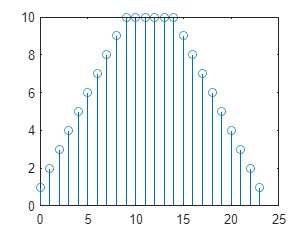

% Insert your code here
n1 = 0:9;
x1 = (n1 >= 0) - (n1 >= 10);
n2 = 0:14;
x2 = (n2 >= 0) - (n2 >= 15);
y = conv(x1, x2);
ny = 0:(length(y) - 1);
stem(ny, y);

### **题目2**：已知${\mathbf{x}}_1 \left(\mathbf{n}\right)=\textrm{n，0}\le n\le 10$，${\mathbf{x}}_2 \left(n\right)=u\left(n+2\right)，-2\le n\le 10$，求两个信号的卷积${\mathit{\mathbf{x}}\left(n\right)=\mathit{\mathbf{x}}}_1 \left(\mathbf{n}\right)$*${\mathbf{x}}_2 \left(\mathbf{n}\right)$，注意n的非零取值范围应为-2~20。

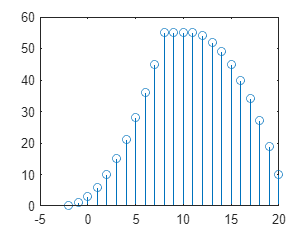

% Insert your code here
n1 = 0:10;
x1 = n1;
n2 = -2:10;
x2 = (n2 >= -2);
y = conv(x1, x2);
ny = -2:20;
stem(ny, y);

### **题目3**：编写MATLAB程序，求以下各序列的z变换。

### 1.${\mathbf{x}}_1 \left(\mathbf{n}\right)=\mathbf{n}{\mathbf{a}}^{\mathbf{n}}$

### 2.${\mathbf{x}}_2 \left(\mathbf{n}\right)={\mathbf{e}}^{-\mathbf{a}\mathbf{n}} \mathbf{s}\mathbf{i}\mathbf{n}\left(\mathbf{n}\omega_0 \right)$

**解答1**：

% Insert your code here
syms a n w0 z
x1n=n*a^n;
x2n=sin(w0*n)*exp(-a*n);
disp('x1(n)的Z变换：')

x1(n)的Z变换：


x1n = ztrans(x1n,n,z); 
disp(x1n);

$$\frac{a\,z}{{\left(a-z\right)}^{2}}$$

disp('x2(n)的Z变换：')

x2(n)的Z变换：


X2 = ztrans(x2n,n,z);
disp(x2n);

$${\mathrm{e}}^{-a\,n}\,\sin\left(n\,w_{0}\right)$$

### **题目4**：已知因果系统的零-极点增益模型分别为：

### 
$$\begin{array}{c}
{\textrm{H}}_1 \left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}-0.3}{{\left(\mathit{\mathbf{z}}+0.5-0.7\mathit{\mathbf{j}}\right)\left(\mathit{\mathbf{z}}+0.5+0.7\mathit{\mathbf{j}}\right)}}\\
{\textrm{H}}_2 \left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}-0.3}{{\left(\mathit{\mathbf{z}}+0.6-0.8\mathit{\mathbf{j}}\right)\left(\mathit{\mathbf{z}}+0.6+0.8\mathit{\mathbf{j}}\right)}}\\
{\textrm{H}}_3 \left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}-0.3}{{\left(\mathit{\mathbf{z}}+1-\mathit{\mathbf{j}}\right)\left(\mathit{\mathbf{z}}+1+\mathit{\mathbf{j}}\right)}}
\end{array}$$


### 求这些系统的零极点分布图以及系统的单位脉冲响应，并判断系统的因果稳定性。

**解答2**：

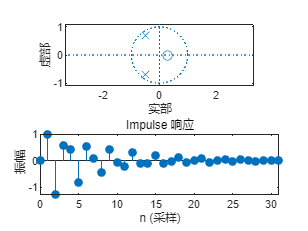

% Insert your code here
z1 = [0.3];
p1 = [-0.5+0.7j, -0.5-0.7j];
z2 = [0.3];
p2 = [-0.6+0.8j, -0.6-0.8j];
z3 = [0.3];
p3 = [-1+j, -1-j];
[b1,a1] = zp2tf(z1,p1,1);
[b2,a2] = zp2tf(z2,p2,1);  
[b3,a3] = zp2tf(z3,p3,1);
N = 32;
figure;
subplot(2,1,1);
zplane(b1,a1);
subplot(2,1,2);
[h1,n1] = impz(b1,a1,N);
impz(b1,a1,N);

poles1 = roots(a1);
if all(abs(poles1) < 1)
	disp('系统一稳定');
else
	disp('系统一不稳定');
end

系统一稳定


系统一因果


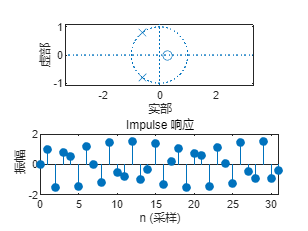

figure;
subplot(2,1,1);
zplane(b2,a2);
subplot(2,1,2);
[h2,n2] = impz(b2,a2,N);
impz(b2,a2,N);

poles2 = roots(a2);
if all(abs(poles2) < 1)
	disp('系统二稳定');
else
	disp('系统二不稳定');
end

系统二不稳定


系统二因果


figure;
subplot(2,1,1);
zplane(b3,a3);
subplot(2,1,2);
[h3,n3] = impz(b3,a3,N);
impz(b3,a3,N);
poles3 = roots(a3);
if all(abs(poles3) < 1)
	disp('系统三稳定');
else
	disp('系统三不稳定');
end

系统三不稳定


系统三因果


### **题目5**：已知离散时间系统的传递函数为：$\textrm{H}\left(z\right)=\frac{2+3{\mathit{\mathbf{z}}}^{-1} }{1+0.4{\mathit{\mathbf{z}}}^{-1} +{\mathit{\mathbf{z}}}^{-2} }$，求该系统在$0-\pi$频率范围内的相对幅度频率响应与相位频率响应曲线。

**解答3**：

% Insert your code here
b = [2,3,0];
a = [1,0.4,1];
[h,w] = freqz(b, a, 512);

mag = abs(h);
mag = mag / max(mag);
mag = 20*log10(mag);
pha = angle(h);

wN = w / pi;

%相对幅频响应
subplot(2,1,1);
plot(wN, mag, 'LineWidth', 1.2);
xlim([0 1]);
ylim([-100 0]);
xlabel('\omega/\pi');
ylabel('相对幅度(dB)');
grid on;

%相频响应
subplot(2,1,2);
plot(wN, pha/pi, 'LineWidth', 1.2);
xlim([0 1]);
xlabel('\omega/\pi');
ylabel('相位/\pi');
grid on;

### **题目6**：已知离散时间系统的零-极点增益模型为：$\mathit{\mathbf{H}}\left(z\right)=\frac{z\left(z+2\right)}{{\left(\mathit{\mathbf{z}}-0.3\right)\left(\mathit{\mathbf{z}}-0.4\right)\left(\mathit{\mathbf{z}}-0.6\right)}}$，求该系统在 $0-\pi$ 频率范围内的绝对幅度频率响应、相对幅度频率响应（先除以最大值，归一化到（0，1]，然后取20*log10（x））、相位频率响应曲线以及零极点分布图，并判断滤波器类型。

**解答4**：

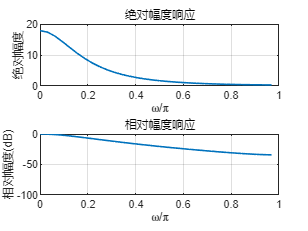

% Insert your code here
z = [0;-2];
p = [0.3 0.4 0.6];
[b,a] = zp2tf(z, p, 1);

N = 32;
[H,w] = freqz(b, a, N);
wN = w / pi;

magAbs = abs(H);
magRel = magAbs / max(magAbs);
magRel_dB = 20*log10(magRel);

%绝对幅度响应
subplot(2,1,1);
plot(wN, magAbs, 'LineWidth', 1.2);
xlim([0 1]);
xlabel('\omega/\pi');
ylabel('绝对幅度');
grid on;
title('绝对幅度响应');
%相对幅度响应
subplot(2,1,2);
plot(wN, magRel_dB, 'LineWidth', 1.2);
xlim([0 1]);
ylim([-100 0]);
xlabel('\omega/\pi');
ylabel('相对幅度(dB)');
grid on;
title('相对幅度响应');

%相频响应
figure;
subplot(2,1,1);
pha = angle(H);
plot(wN, pha, 'LineWidth', 1.2);
xlim([0 1]);
xlabel('\omega/\pi');
ylabel('相位');
grid on;
title('相频响应');
%极零点分布图
subplot(2,1,2);
zplane(b, a);
title('极零点分布图');
%滤波器类型
if all(p > 0) && all(p < 1)
    filterType = '低通滤波器';
elseif all(p < 0) && all(p > -1)
    filterType = '高通滤波器';
elseif all(p > 0) && all(p > 1)
    filterType = '带通滤波器';
elseif all(p < 0) && all(p < -1)
    filterType = '带阻滤波器';
else
    filterType = '未知类型滤波器';
end
disp(['滤波器类型：', filterType]);

滤波器类型：低通滤波器


### **题目7**：已知离散时间系统的系统函数为$H(z)=\frac{0\ldotp 187632-0\ldotp 241242z^{-2} +0\ldotp 241242z^{-4} -0\ldotp 187632z^{-6} }{1+0\ldotp 602012z^{-2} +0\ldotp 495684z^{-4} -0\ldotp 035924z^{-6} }$，求该系统在 $0-\pi$ 频率范围内的绝对幅度频率响应、相对幅度频率响应（关于最大值归一化）、相位频率响应及群延迟，并判断滤波器类型。

**解答5**：

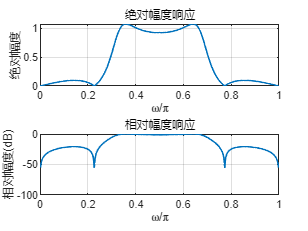

% Insert your code here
b = [0.187632  0 -0.241242 0 0.241242 0 -0.187632];
a = [1 0 0.602012 0 0.495684 0 -0.035924];

N = 512;
[H,w] = freqz(b, a, N);
wN = w / pi;

magAbs = abs(H);
magRel = magAbs / max(magAbs);
magRel_dB = 20*log10(magRel);

%绝对幅度响应
subplot(2,1,1);
plot(wN, magAbs, 'LineWidth', 1.2);
xlim([0 1]);
xlabel('\omega/\pi');
ylabel('绝对幅度');
grid on;
title('绝对幅度响应');
%相对幅度响应
subplot(2,1,2);
plot(wN, magRel_dB, 'LineWidth', 1.2);
xlim([0 1]);
ylim([-100 0]);
xlabel('\omega/\pi');
ylabel('相对幅度(dB)');
grid on;
title('相对幅度响应');

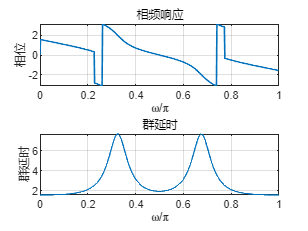

%相频响应
figure;
subplot(2,1,1);
pha = angle(H);
plot(wN, pha, 'LineWidth', 1.2);
xlim([0 1]);
xlabel('\omega/\pi');
ylabel('相位');
grid on;
title('相频响应');
%群延时
subplot(2,1,2);
grpdelay(b, a, N);
xlim([0 1]);
xlabel('\omega/\pi');
ylabel('群延时');
grid on;
title('群延时');

%滤波器类型
if all(p > 0) && all(p < 1)
    filterType = '低通滤波器';
elseif all(p < 0) && all(p > -1)
    filterType = '高通滤波器';
elseif all(p > 0) && all(p > 1)
    filterType = '带通滤波器';
elseif all(p < 0) && all(p < -1)
    filterType = '带阻滤波器';
else
    filterType = '未知类型滤波器';
end
disp(['滤波器类型：', filterType]);

滤波器类型：低通滤波器
